# 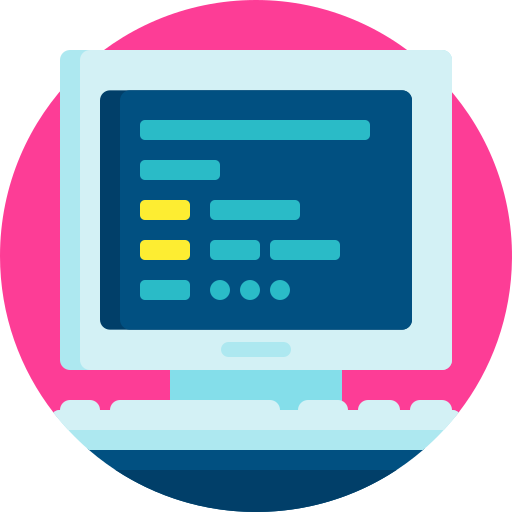

# Virtual Lab 2 - Representing orientation

#### This Virtual Lab covers Section 3.1-3.3 of the course notes

- This Virtual Lab will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive/USB. 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (or CMD+ENTER).

## Introduction

So far, we have been handling our orientation indirectly, using encoded forms, such as the rotation matrix. If required, we can extract the actual orientation descriptor, which we may require for data analysis, filtering, or feedback control (more on this later).

This Virtual Lab will focus on two common ways of representing orientation:

- Euler angles

- quaternions

## Euler angles

A popular choice to describe orientation is to use Euler angles. You will find this approach quite common in literature and research papers. While there are many downsides with this way of describing orientation, it is still worth understanding the fundamental workings of Euler angles.

### Description

In the case of intrinsic *ZYX* Euler angles (see Section 3.2), we can describe the orientation of one frame with respect to another using 

$\eta = \pmatrix{\phi \cr\theta   \cr \psi}$,

where $\phi$, $\theta$, and $\psi$ are referred to as the roll, pitch, and yaw angles, respectively. Notably, these three angles have the following bounds:

- $\{\phi,\psi\}\in[-\pi,\pi]$, 

- $\theta\in[-\frac{\pi}{2},\frac{\pi}{2}]$.

If we know what our Euler angles are, we can construct our ZYX rotation matrix using three sequential rotations about three newly formed axes, which yields

${^W{\bf R}_B}={^W{\bf R}_Z}{^Z{\bf R}_Y}{^Y{\bf R}_B}$.

The "*ZYX" *label above indicates that we sequentially rotate about $\hat{\bf z}_W$, $\hat{\bf y}_Z$, and $\hat{\bf x}_Y$, where frame${\{Z\}$describes the orientation after rotating about $\hat{\bf z}_W$, and frame ${\{Y\}$ describes the orientation after rotating about $\hat{\bf y}_Z$. Specifically, we will be systematically moving through four reference frames: ${\{W\} \rightarrow {\{Z\} \rightarrow {\{Y\} \rightarrow {\{X\} ={\{B\} $, which is illustrated in the figure below.

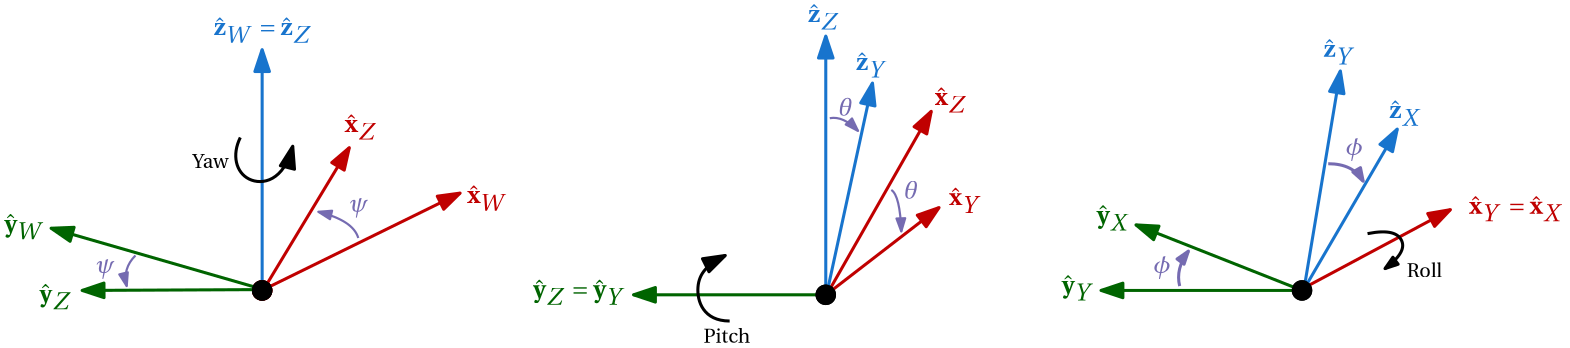

We can visualise the rotations using the code below, using a fixed-wing UAV as our robot of interest.

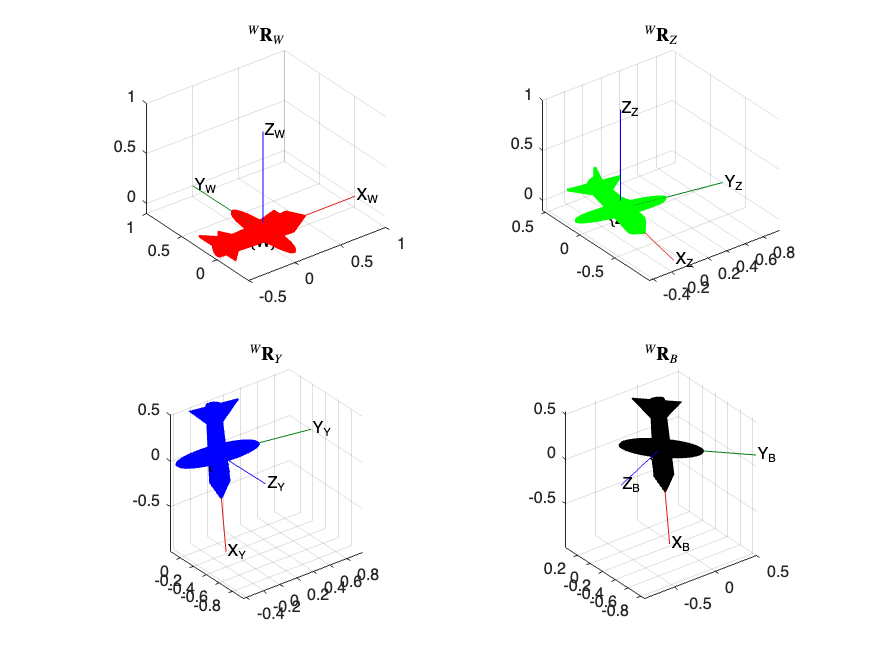

phi = 50*pi/180;
the = 80*pi/180;
psi = -100*pi/180;

Rz = [cos(psi) -sin(psi) 0;
      sin(psi) cos(psi) 0;
      0          0       1];
Ry = [cos(the)   0   sin(the);
      0          1       0;
     -sin(the)   0   cos(the)];
Rx = [1     0        0;
      0 cos(phi) -sin(phi);
      0 sin(phi) cos(phi)];

figure,hold on
subplot(2,2,1),plotTransforms([0 0 0],rotm2quat(eye(3)),"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf R}_W$',Interpreter='latex'),grid on
subplot(2,2,2),plotTransforms([0 0 0],rotm2quat(Rz),"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('$^W{\bf R}_Z$',Interpreter='latex'),grid on
subplot(2,2,3),plotTransforms([0 0 0],rotm2quat(Rz*Ry),"MeshFilePath",'fixedwing.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","Y")
axis equal, title('$^W{\bf R}_Y$',Interpreter='latex'),grid on
subplot(2,2,4),plotTransforms([0 0 0],rotm2quat(Rz*Ry*Rx),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B")
axis equal, title('$^W{\bf R}_B$',Interpreter='latex'),grid on

Note (based on how we have used `plotTransforms` above) that we chained together the rotation matrices as needed when deriving the new frame orientation. The matrix multiplication order is also very important and is required to follow the convention stated for the particular Euler angle vector. 

**  Question 1: **Given that ${^W{\bf R}_B}={^W{\bf R}_Z}{^Z{\bf R}_Y}{^Y{\bf R}_B}$, under what generalised condition will ${^W{\bf R}_B}={^Y{\bf R}_B}$?

**Answer: **${^W{\bf R}_Z}={^Z{\bf R}^{-1}_Y}$.

We can also recover the Euler angles from a rotation matrix, if need be, using the equations below


$$\begin{array}{cc}\phi = \arctan(\frac{r_{32}}{r_{33}})\end{array},$$
     
$$\begin{array}{cc}\theta = -\arcsin{r_{31},\end{array}$$
     
$$\begin{array}{cc}\psi = \arctan(\frac{r_{21}}{r_{11}}),\end{array}$$


where


$$\begin{array}{cc}^W{\mathbf R}_B = \left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right]=    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right]    .\end{array}$$


**  Question 2: **Given a rotation matrix of $\begin{array}{cc}^W{\mathbf R}_B = \left[\begin{array}{cccccccc}    -0.0302 & 0.502 & -0.864 \\    -0.171 & -0.855 & -0.490 \\    -0.985 & 0.1335 & 0.112    \\ \end{array}\right]   \end{array}$, determine the corresponding roll-pitch-yaw angles in degrees.

%Code block (if required)
R = Rz*Ry*Rx;
R_ = [-.0302 0.502 -0.864; -0.171 -0.855 -0.490; -0.985 0.1335 0.112];

phi_ = atan2( R_(3,2),R_(3,3) )*180/pi

phi_ =   50.004987270512885


theta_ = -asin( R_(3,1) )*180/pi

theta_ =   80.063632927859274


psi_ = atan2( R_(2,1),R_(1,1) )*180/pi

psi_ =     -1.000156253551073e+02


### Gimbal lock

One of the main problems with using Euler angles is when two rotation axes used in defining the rotation order become aligned (parallel or anti-parallel), thereby resulting in the loss of one rotational degree of freedom. This is known as *gimbal lock *and occurs when the first and third rotation take place about the same inertial-frame axis.

**  Question 3: **What value(s) of $\theta$ result in gimbal lock when using *ZYX* intrinsic Euler angles?

**Answer: **$\theta=\pm 90^\circ$.

%Code block (if required)


We can test out the gimbal lock phenomenon by specifying two different sets of ZYX Euler angles while in gimbal lock and showing that they result in the same orientation when adding the roll and yaw angles about $\pm\hat{\bf z}_W$. Specifically, if the first and third axes become parallel, the roll and yaw angles sum, whereas when the first and third axes are anti-parallel, the roll and yaw are differenced, based on right-hand rule. If we have the correct combination of Euler angles while in gimbal lock, the resulting axes from the code block should match in orientation.

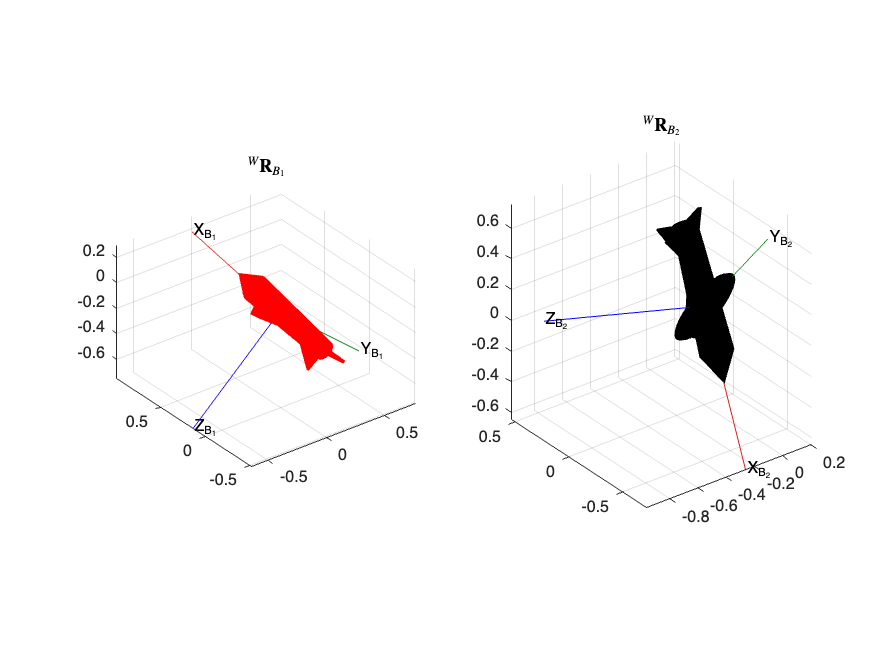

phi1 = -140*pi/180;   phi2 = 80*pi/180; 
the1 = -10*pi/180;    the2 = 40*pi/180;
psi1 = 90*pi/180;   psi2 = -110*pi/180;

Rz1 = [cos(psi1) -sin(psi1) 0; %principle rotation about z-axis
      sin(psi1) cos(psi1) 0;
      0          0       1];
Ry1 = [cos(the1)   0   sin(the1);  %principle rotation about y-axis
      0          1       0;
     -sin(the1)   0   cos(the1)];
Rx1 = [1     0        0;     %principle rotation about x-axis
      0 cos(phi1) -sin(phi1);
      0 sin(phi1) cos(phi1)];

Rz2 = [cos(psi2) -sin(psi2) 0; %principle rotation about z-axis
      sin(psi2) cos(psi2) 0;
      0          0       1];
Ry2 = [cos(the2)   0   sin(the2);  %principle rotation about y-axis
      0          1       0;
     -sin(the2)   0   cos(the2)];
Rx2 = [1     0        0;     %principle rotation about x-axis
      0 cos(phi2) -sin(phi2);
      0 sin(phi2) cos(phi2)];

figure,hold on
subplot(1,2,1),plotTransforms([0 0 0],rotm2quat(Rz1*Ry1*Rx1),"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","B_1")
axis equal, title('$^W{\bf R}_{B_1}$',Interpreter='latex'),grid on
subplot(1,2,2),plotTransforms([0 0 0],rotm2quat(Rz2*Ry2*Rx2),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B_2")
axis equal, title('$^W{\bf R}_{B_2}$',Interpreter='latex'),grid on

**  Question 4: **Given a ZYX Euler angle vector of $\eta=\left[20^\circ ~~90^\circ ~~20^\circ\right]^T$, select the other Euler angle vector(s) that result in the same orientation.

**Answer:** $\eta=\left[0^\circ ~~90^\circ ~~0^\circ\right]^T$,  $\eta=\left[25^\circ ~~90^\circ ~~25^\circ\right]^T$—* from list of options on Amathuba.*

%Code block (if required)


**  Question 5: **Assuming $\theta \in [-90^\circ,90^\circ]$, what value(s) of $\theta$ result in gimbal lock when using ZYZ intrinsic Euler angles?

**Answer: **$\theta=0^\circ$.

%Code block (if required)


## Quaternions 

Euler angles are appealing as an introduction to understanding orientation, as they are intuitively pleasing and relatively easy to visualise. However, the potential for our orientation representation becoming degenerate and resulting in kinematic singularities raises a red flag for many robotic applications. Additionally, the idea of describing an orientation using three sequential rotations does not follow how rigid-body robot motion will evolve in general. Instead, we would expect pure rotations about some arbitrary axis — enter the quaternion! 

The **quaternion** is a popular choice of encoding attitude that can completely avoid the issue of gimbal lock by rather describing the orientation as a single rotation about some defined axis that intercepts the relevant reference frame origin. At first glance, the quaternion can seem a bit daunting, but the benefits of understanding and being able to utilise it in robotics (among other fields) is worth the time investment that you may need to understand it. We will also see later in Section 3.4 that quaternions are closely related to exponential coordinates — another powerful and yet intuitive way to describe orientation.

### Definition

The quaternion, $\bf q$ , is a 4-element vector (also known as a 4-tuple) and is structured as


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    q_0 \\ q_x \\ q_y \\ q_z    \\ \end{array}\right],\end{array}$$


in which$\{q_0, q_x, q_y,q_z\}$ are real numbers. In the context of describing orientation, we only consider *unit quaternions*, which gives us the unit-norm constraint of


$$\begin{array}{cc} |{\bf q}|=q_0^2+ q_x^2+ q_y^2+ q_z^2 = 1.\end{array}$$


Explicitly, the unit quaternion follows an *angle-axis* structure of 


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\ \sin{\frac{\alpha}{2}} \hat{\mathbf v}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\     \sin{\frac{\alpha}{2}} v_x \\    \sin{\frac{\alpha}{2}} v_y \\    \sin{\frac{\alpha}{2}} v_z    \\ \end{array}\right],\end{array}$$


where  $\hat{\mathbf v}=[v_x ~v_y ~v_z]^T$ is the unit-length ( $|\hat{\mathbf v}|=1$ ) rotation axis, and  $\alpha \in [-\pi,\pi)$ is the rotation angle, as shown in the figure below for the case when the rotation vector is described with respect to $\{W\}$.

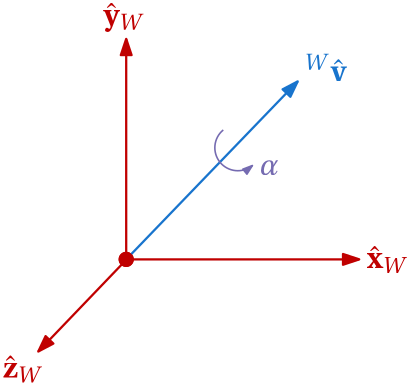

The code block below also shows how the quaternion axis-angle form can be used to rotate a rigid body, such as a quadcopter. The black line shows the rotation axis, $\hat{\bf v}$.

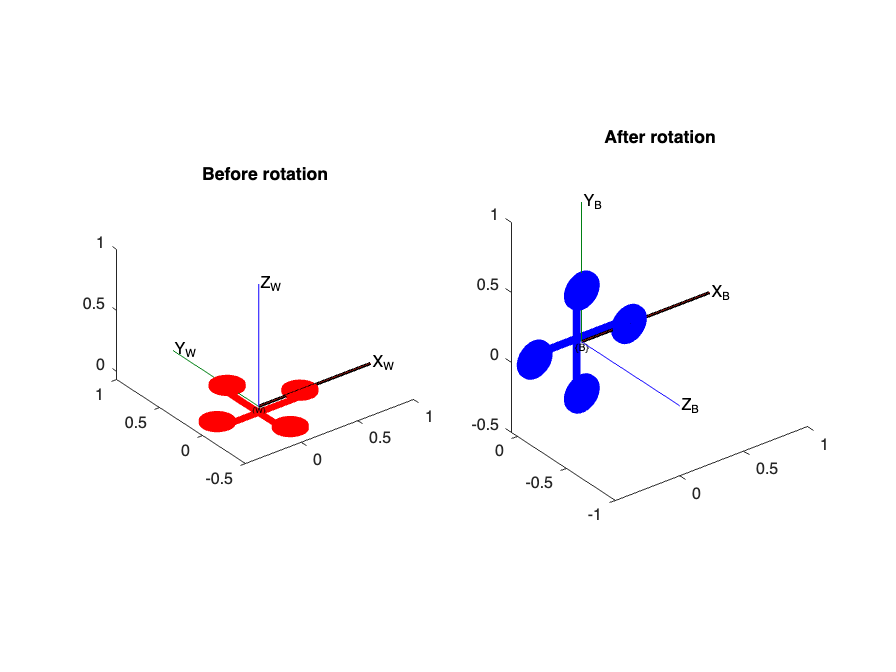

v_x = 1;
v_y = 0;
v_z = 0;
v = [v_x v_y v_z]'; 
v = v/norm(v);  %normalise v so that it always has unit length.

theta = 90*pi/180;
q = [cos(theta/2); sin(theta/2)*v];

figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('Before rotation')

subplot(1,2,2)
plotTransforms([0 0 0],q',"MeshFilePath",'multirotor.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","B")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('After rotation') 

**  Question 6: **Determine the quaternion that corresponds to a rotation of $\pi/2$ about vector $\hat{\mathbf v}=[\frac{1}{\sqrt{2}} ~~\frac{1}{\sqrt{2}} ~~0]^T$.

%Code block (if required)
alpha = pi/2;
v = [1/sqrt(2) 1/sqrt(2) 0];
q = [cos(alpha/2) sin(alpha/2)*v]

q =    0.707106781186548   0.500000000000000   0.500000000000000                   0


The explicit quaternion form of


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\ \sin{\frac{\alpha}{2}} \hat{\mathbf v}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\     \sin{\frac{\alpha}{2}} v_x \\    \sin{\frac{\alpha}{2}} v_y \\    \sin{\frac{\alpha}{2}} v_z    \\ \end{array}\right]
=     \left[\begin{array}{cc}    q_0 \\     q_x \\    q_y \\    q_z    \\ \end{array}\right]
\end{array}$$


is a way of *encoding* the 3D rotation of $\alpha$ about $\hat{\bf v}$ in a useful format, analogous to how rotation matrices encode attitude. Assuming we are given ${\bf q } = \left[q_0 ~~ q_x ~~ q_y ~~ q_z \right]^T$, we can always extract the angle-axis information from our quaternion representation using 


$$\begin{array}{cc}\alpha = 2\cos^{-1}(q_0),\end{array}$$


and 


$$\begin{array}{cc}\hat{\mathbf v} = \frac{1}{\sin{\frac{\alpha}{2}}}\left[\begin{array}{cc}    q_x \\ q_y \\ q_z    \\ \end{array}\right] =     \frac{1}{\sqrt{1-q_0^2}}    \left[\begin{array}{cc}    q_x \\ q_y \\ q_z    \\ \end{array}\right].\end{array}$$


When  $q_0=1$ , (which implies that  $\alpha=0$ ), the equation above tends to infinity, making the rotation axis become undefined. However, this is not problematic, as $\alpha=0$ corresponds to the null rotation matrix of  ${\mathbf R}={\mathbf I}$. In essence, we cannot determine the rotation vector because there is no rotation taking place. In this case, we would describe the identity (or null) quaternion as  ${\mathbf q}_{\mathbf I}=[1~ 0~ 0~ 0]^T$ . Given an angle-axis combination, we can now describe the corresponding quaternion


$$\{\alpha,\hat{\mathbf v}\}\rightarrow {\mathbf q},$$


and similarly, given a quaternion, we can recover our angle-axis pair


$${\mathbf q}\rightarrow \{\alpha,\hat{\mathbf v}\}.$$


**  Question 7: **Determine the rotation angle and vector corresponding to the quaternion: ${\bf q} = \left[ 0.5~~-0.5~~-0.5~~0.5\right]^T$.

%Code block (if required)
q = [0.5 -0.5 -0.5 0.5];
alpha = 2*acos( q(1) )

alpha =    2.094395102393196


v = 1/sqrt(1-q(1)^2)*q(2:4)

v =   -0.577350269189626  -0.577350269189626   0.577350269189626


As with Euler angles, there exists a one-to-one mapping between the quaternion representation and rotation matrix, given by


$$\begin{array}{cc}{\mathbf R} = \left[\begin{array}{cccccccc}    2(q_0^2+q_x^2)-1 & 2(q_xq_y-q_0q_z) & 2(q_xq_z+q_0q_y) \\    2(q_xq_y+q_0q_z) & 2(q_0^2+q_y^2)-1 & 2(q_yq_z-q_0q_x) \\    2(q_xq_z-q_0q_y) & 2(q_yq_z+q_0q_x) & 2(q_0^2+q_z^2)-1    \\ \end{array}\right].\end{array}$$


For $q_0\neq 0$, which implies that $\alpha \neq \pm \pi$, extraction of the quaternion from a rotation matrix is achieved using

$q_0=\frac{1}{2}\sqrt{1+\text{tr}{\bf R}},$     $q_x=\frac{r_{32}-r_{23}}{4q_0}$,     $q_y=\frac{r_{13}-r_{31}}{4q_0}$,      $q_z=\frac{r_{21}-r_{12}}{4q_0},$

where 

$\begin{array}{cc}{\mathbf R} = \left[\begin{array}{cccccccc}    2(q_0^2+q_x^2)-1 & 2(q_xq_y-q_0q_z) & 2(q_xq_z+q_0q_y) \\    2(q_xq_y+q_0q_z) & 2(q_0^2+q_y^2)-1 & 2(q_yq_z-q_0q_x) \\    2(q_xq_z-q_0q_y) & 2(q_yq_z+q_0q_x) & 2(q_0^2+q_z^2)-1    \\ \end{array}\right]\end{array}=\left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right]$,

and $\text{tr}{\bf R}$ corresponds to the trace (summing diagonal elements) or matrix $\bf R$, namely


$$\text{tr}{\bf R}=r_{11}+r_{22}+r_{33}.$$


If $q_0=0$, implying that  that $\alpha = \pm \pi$, the equation above for determining the vector part of $\bf q$ will result in a singularity. In this case, we can instead determine $\{q_x,q_y,q_z\}$ using

$q_x=\sqrt{\frac{r_{11}+1}{2}}$,     $q_y=\sqrt{\frac{r_{22}+1}{2}}$,     $q_z=\sqrt{\frac{r_{33}+1}{2}}$.

**  Question 8: **Show mathematically, by hand, that $q_0=\frac{1}{2}\sqrt{1+\text{tr}{\bf R}}$ in general.

**Answer: **


$$\begin{array}{ll}
\text{tr}{\bf R}
&=r_{11}+r_{22}+r_{33},\\
&=2(q_0^2+q_x^2)-1 +2(q_0^2+q_y^2)-1+2(q_0^2+q_z^2)-1,\\
&=4q_0^2+2(q_0^2+q_x^2+q_y^2+q_z^2)-3,\\
&=4q_0^2-1.\\
\end{array}$$



$$\begin{array}{ll}
q_0
&=\frac{1}{2}\sqrt{1+\text{tr}{\bf R}},\\
&=\frac{1}{2}\sqrt{1+4q_0^2-1},\\
&=q_0.
\end{array}$$


%Code block (if required)


### Quaternion multiplication

Just as we were able to sequentially construct our body-frame orientation by using the elementary rotations when dealing with Euler angles, we can follow a similar process for the quaternion. However, we first need to cover how quaternion multiplication works. Given two quaternions, $\bf q$ and $\bf r$ , the quaternion product (or Hamilton Product), indicated using the symbol $\otimes$, is defined as


$$\begin{array}{cc}{\mathbf q} \otimes {\mathbf r} =     \left[\begin{array}{cc}    q_0r_0-q_xr_x-q_yr_y-q_zr_z \\    q_0r_x+r_0q_x+q_yr_z-r_yq_z \\    q_0r_y+r_0q_y+r_xq_z-q_xr_z \\    q_0r_z+r_0q_z+q_xr_y-r_xq_y    \\ \end{array}\right].\end{array}$$


This stems from the fact that $\bf q$ and $\bf r$ can be written as


$${\bf q} = q_0+q_x\hat{\bf i}+q_y\hat{\bf j}+q_z\hat{\bf k},$$


${\bf r} = r_0+r_x\hat{\bf i}+r_y\hat{\bf j}+r_z\hat{\bf k}$,

respectively, where $\{\hat{\bf i},\hat{\bf j},\hat{\bf k}\}$ are the basis vectors indicating direction. Using the relationship of


$$\hat{\bf i}^2=\hat{\bf j}^2=\hat{\bf k}^2=\hat{\bf i}\hat{\bf j}\hat{\bf k}=-1$$


yields the abovementioned result of 


$$\begin{array}{ll}{\mathbf q} \otimes {\mathbf r} &=    
\left(q_0+q_x\hat{\bf i}+q_y\hat{\bf j}+q_z\hat{\bf k}\right)\left(r_0+r_x\hat{\bf i}+r_y\hat{\bf j}+r_z\hat{\bf k}\right)\\
&= \left( q_0r_0-q_xr_x-q_yr_y-q_zr_z \right)+\left(q_0r_x+r_0q_x+q_yr_z-r_yq_z  \right)\hat{\bf i}+\left( q_0r_y+r_0q_y+r_xq_z-q_xr_z \right)\hat{\bf j}+\left(q_0r_z+r_0q_z+q_xr_y-r_xq_y \right)\hat{\bf k}\\
&= \left[\begin{array}{cc}    q_0r_0-q_xr_x-q_yr_y-q_zr_z \\    q_0r_x+r_0q_x+q_yr_z-r_yq_z \\    q_0r_y+r_0q_y+r_xq_z-q_xr_z \\    q_0r_z+r_0q_z+q_xr_y-r_xq_y    \\ \end{array}\right].
\end{array}$$


You need not be too concerned about the finer details of this operation (this will not be examined in detail in this course), just be aware that the multiplication of 4-tuples is different to what you are probably used to! 

Continuing with our exercise of emulating the sequential construction of our body-frame orientation as was done using ZYX Euler angles, we begin by configuring the two reference frames such that they are aligned and coincident. We then apply a rotation about  $\hat{\mathbf z}_W=[0~0~1]^T$ , with an angle of $\psi$, which gives us 


$$\begin{array}{cc}{^W{\mathbf q}}_Z = \left[\begin{array}{cc}          \cos{\frac{\psi}{2}} \\          0 \\          0 \\          \sin{\frac{\psi}{2}}          \\ \end{array}\right].\end{array}$$


We next rotate about  $\hat{\mathbf y}_Z=[0~1~0]^T$ with an angle of  $\theta$, which is encoded by the incremental quaternion of 


$$\begin{array}{cc}^Z{\mathbf q}_Y = \left[\begin{array}{cc}          \cos{\frac{\theta}{2}} \\          0 \\          \sin{\frac{\theta}{2}}\\          0           \\ \end{array}\right].\end{array}$$


Lastly, we rotate about  $\hat{\mathbf x}_Y=[1~0~0]^T$, with an angle of  $\phi$, which is described by the incremental quaternion of 


$$\begin{array}{cc}^Y{\mathbf q}_B = \left[\begin{array}{cc}          \cos{\frac{\phi}{2}} \\          \sin{\frac{\phi}{2}}\\          0 \\          0           \\ \end{array}\right].\end{array}$$


Our full description of the body-frame orientation, using the quaternion as our *encoder* follows as


$$\begin{array}{cc}{^W{\mathbf q}_B}={^W{\mathbf q}_Z} \otimes {^Z{\mathbf q}_Y} \otimes {^Y{\mathbf q}_B},\end{array}$$


and is analogous to the rotation matrix equivalent of $\begin{array}{cc}{^W {\mathbf R}_B} = {^W {\mathbf R}_Z}{^Z {\mathbf R}_Y}{^Y {\mathbf R}_B}.\\ \end{array}$ The code block below shows how to perform quaternion multiplication in `MATLAB `and also illustrates that the quaternion representation of attitude matches that of the rotation matrix counterpart.

phi = 90*pi/180;    %set roll angle about x axis of {Y}
the = 30*pi/180;     %set pitch angle about y axis of {Z}
psi = 0*pi/180;    %set yaw angle about z axis of {W}

q_z2w = [cos(psi/2) 0 0 sin(psi/2)];    %quaternion representation of yaw rotation about z in {W}
q_y2z = [cos(the/2) 0 sin(the/2) 0];    %quaternion representation of pitch rotation about y in {Z}
q_b2y = [cos(phi/2) sin(phi/2) 0 0];    %quaternion representation of roll rotation about x in {Y}

q_b2w = quatmultiply( quatmultiply(q_z2w,q_y2z), q_b2y )    %full quaternion describing orientation of {B} wrt {W}

q_b2w =    0.683012701892219   0.683012701892219   0.183012701892219  -0.183012701892219


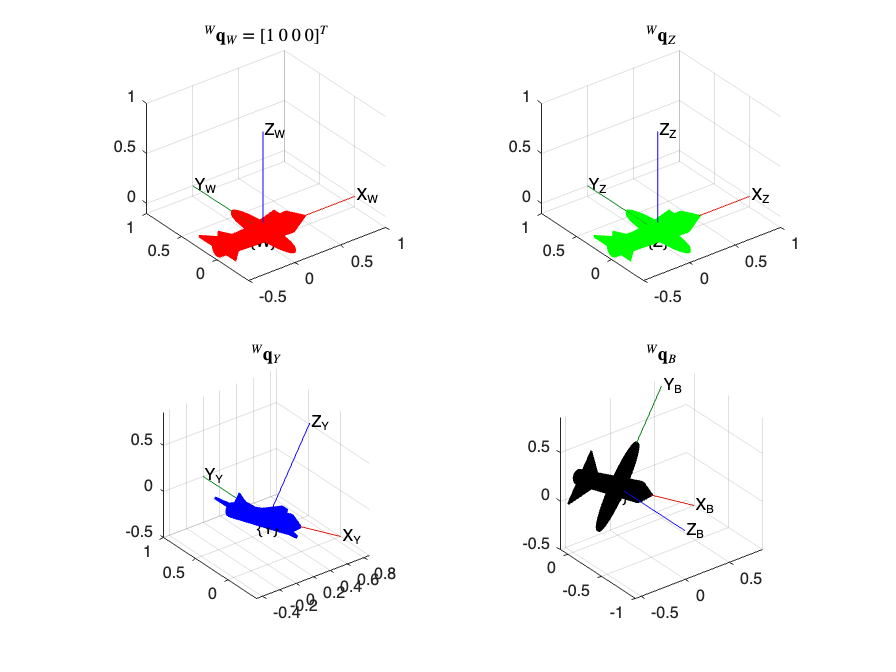


%plot figures
figure,hold on
subplot(2,2,1),plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf q}_W=[1~0~0~0]^T$',Interpreter='latex'),grid on
subplot(2,2,2),plotTransforms([0 0 0],q_z2w,"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('$^W{\bf q}_Z$',Interpreter='latex'),grid on
subplot(2,2,3),plotTransforms([0 0 0],quatmultiply(q_z2w,q_y2z),"MeshFilePath",'fixedwing.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","Y")
axis equal, title('$^W{\bf q}_Y$',Interpreter='latex'),grid on
subplot(2,2,4),plotTransforms([0 0 0],quatmultiply( quatmultiply(q_z2w,q_y2z),q_b2y),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B")
axis equal, title('$^W{\bf q}_B$',Interpreter='latex'),grid on

As with the Euler angles, we have followed the ordering of $\{W\} \rightarrow \{Z\} \rightarrow \{Y\} \rightarrow \{B\}.$ Quaternions can also be thought of as being intrinsic or extrinsic — when post-multiplying by a quaternion, we can imagine the rotation vector being described in the current frame (as above), whereas when pre-multiply the vector is described in $\{W\}$.

Note that in this particular case, our quaternions are still parameterised by the Euler angles. This is not how we will usually make use of quaternions; rather, this is a demonstration of how quaternion rotation works, and its relationship with Euler angles and rotation matrices.

**  Question 9: **Determine the quaternion corresponding to a principal axis rotation of $\begin{array}{cc}{\mathbf R} = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & \cos{\phi} & -\sin{\phi} \\    0 & \sin{\phi} & \cos{\phi}    \\ \end{array}\right].\\ \end{array}$

%Code block (if required)
v = [1 0 0];
syms phi real
q = [cos(phi/2) sin(phi/2)*v]

$$q = \left(\begin{array}{cccc} \cos\left(\frac{\varphi }{2}\right) & \sin\left(\frac{\varphi }{2}\right) & 0 & 0 \end{array}\right)$$

It is worth highlighting the numerical efficiency of the quaternion — while multiplying two rotation matrices requires 27 multiplications and 18 additions, quaternion multiplication only requires 16 multiplications and 12 additions. This may seem insignificant, but in certain applications where processing power is limited, or a large number of coordinate mappings are required (e.g. in the video game instustry) this FLOP saving is envaluable! 

As with the rotation matrix, the quaternion has an inverse, defined as


$$\begin{array}{cc}{\mathbf q}^{-1} = \left[\begin{array}{cc}    q_0 \\    -q_x \\    -q_y \\    -q_z    \\ \end{array}\right].\end{array}$$


We can think of this inverse in one of two ways: either 

- (i) the rotation vector changes direction and points in the opposite direction, or 

- (ii) the rotation angle changes direction. 

In either case, the quaternion inverse can be thought of as "undoing" a rotation. 

If we rotated our robot such that our quaternion was  ${\mathbf a}=[a_0 ~a_x ~a_y ~a_z]^T$ , followed by multiplication of the inverse,  ${\mathbf a}^{-1}=[a_0 ~-a_x ~-a_y ~-a_z]^T$ , we would return to our identity quaternion,  ${\mathbf a}^{-1}\otimes {\mathbf a}=[1 ~0 ~0 ~0]^T$ . 

alpha = 45*pi/180;    %set rotation angle
vx = [1 1 1];     %define arbitrary vector
vx = vx/norm(vx);    %set vector norm to one

q = [cos(alpha/2) sin(alpha/2)*vx];    %quaternion describing rotation

q_I = quatmultiply( quatinv(q),q )    %quaternion multiplied by its inverse, which always returns the null quaternion

q_I =      1     0     0     0


### Rotating a frame

The sequential process of building a quaternion using the principal axis rotations is useful for demonstrating the parallel between rotation matrices and quaternions, but there is actually no need to ever use Euler angles when incorporating quaternions. As previously mentioned, the orientation can be defined using a rotation vector,  $\hat{\mathbf v}$ , and rotation angle $\alpha$ about  $\hat{\mathbf v}$ . In other words, we can define a mapping between two reference frames by either rotating about a single vector with a specific rotation angle (encoded as a quaternion), or equivalently performing three sequential rotations about the intrinsic axes (Euler-parameterised rotation matrix). 

The quaternion approach is generally quite appealing for robotics, as it matches the "natural" rotational behaviour of rigid bodies. That is, incremental rotations will occur as a single motion, not three discrete motions. Later Chapters will also demonstrate that quaternions are highly beneficial when confronting the rigid-body robotic trajectory generation, orientation estimation, and control problem, whereas Euler angles can become problematic in most cases. 

The code block below shows how rotation about a vector can be visualised, with the resulting pose after the rotation facilitated using quaternions.

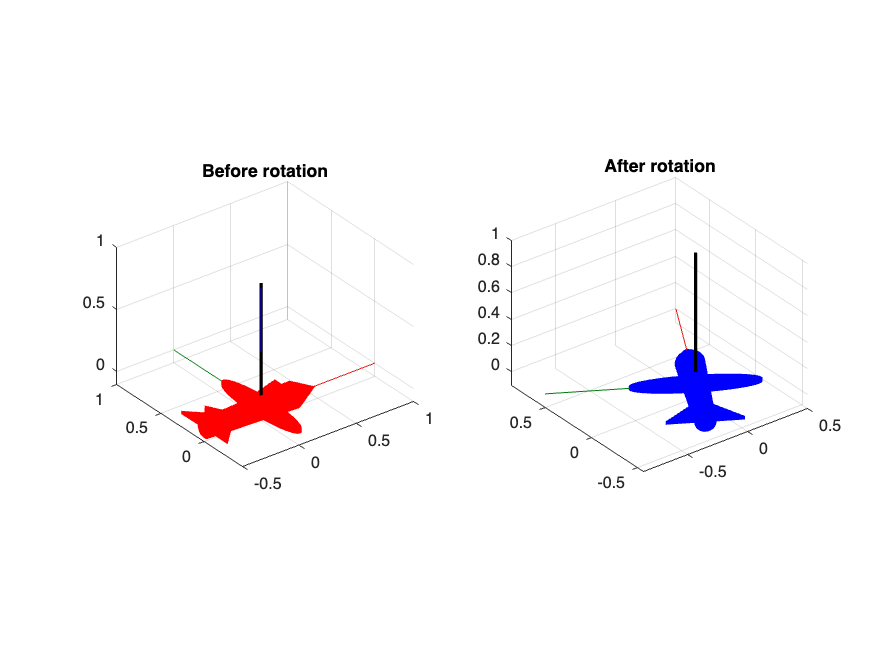

v_x = 0;    %x component of rotation vector
v_y = 0;    %y component of rotation vector
v_z = 1;    %z component of rotation vector
v = [v_x v_y v_z]';  %full rotation vector
v = v/norm(v);  %normalise v so that it always has unit length

alpha = 60*pi/180;    %rotation angle
q = [cos(alpha/2); sin(alpha/2)*v];    %quaternion, formed from combination of rotation angle and rotation vector

%plot figures
figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'fixedwing.stl',"MeshColor","red")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('Before rotation'),grid on

subplot(1,2,2)
plotTransforms([0 0 0],q',"MeshFilePath",'fixedwing.stl',"MeshColor","blue")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('After rotation'),grid on

### Double cover

There is one *minor* caveat that should be made clear when using quaternions. We are operating in a 3D Euclidean space, but the quaternion is a $4$-element vector. So why does the quaternion have $4$ parameters to specify a 3D orientation? The simple answer is that a single quaternion does not uniquely define an orientation. That is, the orientation derived using a rotation about some axis is equivalent to a negative rotation about that same axis after it has been inverted. This results in a **double cover** phenomenon where  $\mathbf q$ and  $-{\mathbf q}$ represent the same rotation. 

The code block demonstrates this result in general, showing that orientation $\mathbf q$ and  $-{\mathbf q}$ are equivalent.

q0 = 1; %set scalar component of quaternion
qx = 0.2; %set x component of quaternion
qy = 0.7; %set y component of quaternion

dq =      0     0     0     1


qz = 0.4; %set z component of quaternion
q = [q0 qx qy qz]; %unnormalised quaternion

q_b1_ =      0     1     0     0


q = q/norm(q); %normalised quaternion

%plot figures
figure,hold on
subplot(1,2,1),plotTransforms([0 0 0],q,"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title(['Rotation described by ','$\bf q$'],Interpreter='latex'),grid on
subplot(1,2,2),plotTransforms([0 0 0],-q,"MeshFilePath",'multirotor.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title(['Rotation described by ','$\bf -q$'],Interpreter='latex'),grid on

As a result of this double covering, every orientation will map to two quaternions; one that describes the minimum angle rotation, $|\alpha|\leq \pi$, and the other describing the maximum angle rotation, $|\alpha|\geq \pi$. The only exception is the special case where the rotation angle is $180^\circ$ , making both rotations equivalent in terms of angular distance. This disparity between a minimum and maximum angle rotation becomes important when our robot is trying to follow a path or correct an angular error, as we commonly desire minimal angular changes that result in smaller time and energy requirements (the minimum angle rotation). This is often referred to as the geodesic.

**  Question 10: **Given that a robotic platform has an initial orientation of ${^W{\bf q}_{B_0}} = \left[ 0~~0~~1~~0\right]^T$, and a final orientation of ${^W{\bf q}_{B_1}} = \left[ 0~~1~~0~~0\right]^T$, determine the quaternion ${^{B_0}{\bf q}_{B_1}}$ that rotates $\{B_0\}$ to $\{B_1\}$.

%Code block (if required)
q_b0 = [0 0 1 0];
q_b1 = [0 1 0 0];
dq = quatmultiply( quatconj(q_b0),q_b1 )

q_b1_ = quatmultiply(q_b0,dq)

**  Question 11: **Upload your completed Virtual Lab .mlx file in Amathuba. Make sure to include your student number in the file name.